clear; clc;
r0 = 1e-6;
R  = 10;                        
rspan = [r0 R];

tol_target = 1e-8;
Q_left  = 0;
Q_right = 15;
state = 2;
opts = odeset('RelTol',1e-10,'AbsTol',1e-10,'Events',@asymptotic_event);

[r_sol, Q_sol, Q0_star] = find_nth_state(state, opts, rspan, Q_left, Q_right, tol_target);

     1



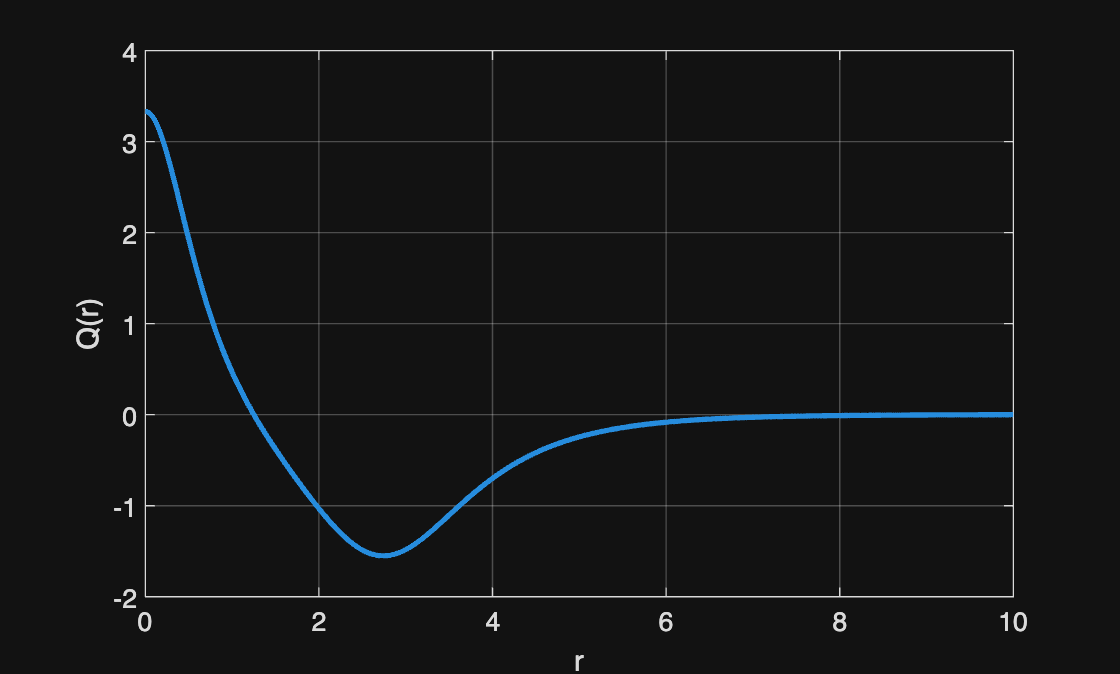


if Q_sol(1) < 0
    Q_sol = -Q_sol;
end

plot(r_sol, Q_sol, 'LineWidth', 2);
hold on;
xlabel('r');
ylabel('Q(r)');
grid on;

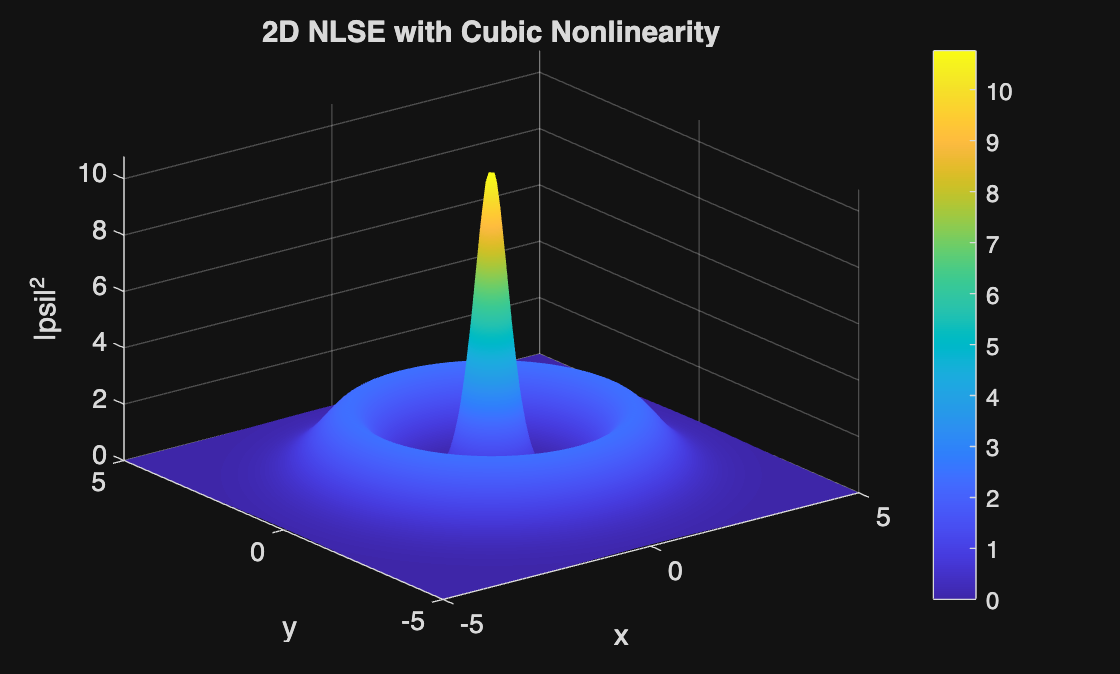


% --- Simulation params ---
Mx = 512;           % grid points in x
My = 512;           % grid points in y
a  = 20;            % domain [-a,a] x [-a,a]
dt = 0.01;
T  = 3;

dx = 2*a/Mx;
dy = 2*a/My;

x = linspace(-a, a-dx, Mx);   % x-grid
y = linspace(-a, a-dy, My);   % y-grid
[X,Y] = meshgrid(x,y);        % 2D physicsal grid

% --- NLSE params ---
epsilon = -1;

%Interpolation of Numerically Evaluated State
R_grid = sqrt(X.^2 + Y.^2);
Q_on_R = interp1(r_sol, Q_sol, R_grid, 'spline', 0);   
psi = Q_on_R;   

mx = (-Mx/2 : Mx/2-1);         % modes in x
my = (-My/2 : My/2-1);         % modes in y

kx = (pi/a) * mx;              % wave numbers in x
ky = (pi/a) * my;              % wave numbers in y

[KX,KY] = meshgrid(kx,ky);     % 2D wave-number grid
lambda = KX.^2 + KY.^2;        % eigenvalues 

K = exp(-1i * lambda * dt/2);  % half-step kinetic operator

figure
h = surf(X, Y, abs(psi).^2);
shading interp            % smoother look (optional)
colorbar                  % show color scale
xlabel('x'); ylabel('y'); zlabel('|psi|^2');
title('2D NLSE with Cubic Nonlinearity');
xlim([-5,5])
ylim([-5,5])
axis manual         

t = 0;

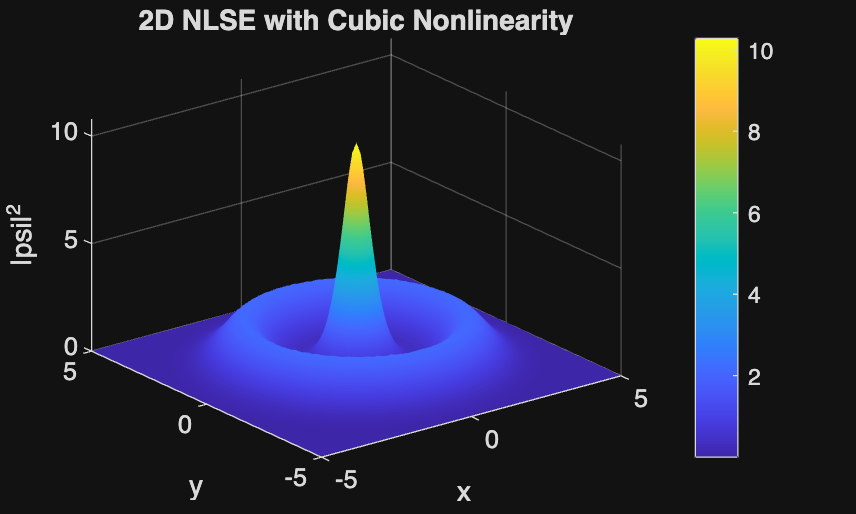

%Time Evolution 
while t < T

    % Fourier transform 
    psi_hat = fftshift(fft2(psi));

    % 1st half-step kinetic
    psi_hat = K .* psi_hat;

    psi = ifft2(ifftshift(psi_hat));

    % Nonlinear step
    psi = exp(-1i*epsilon*dt*abs(psi).^2) .* psi;

    psi_hat = fftshift(fft2(psi));

    % 2nd half-step 
    psi_hat = K .* psi_hat;

    psi = ifft2(ifftshift(psi_hat));

    t = t + dt;
    set(h, 'ZData', abs(psi).^2);
    drawnow;
end